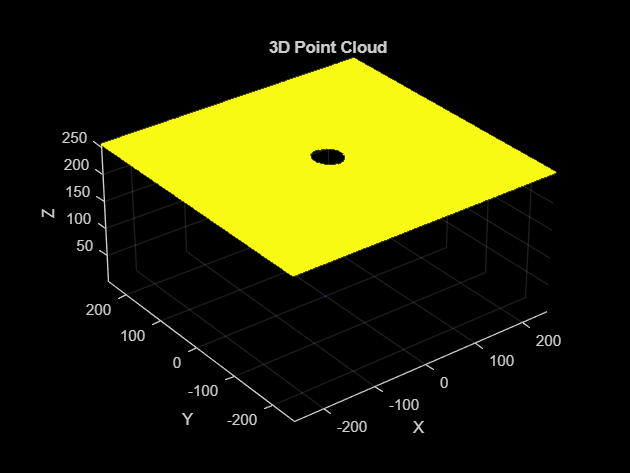

image = imread('depth1.png');
[rows, cols, channels] = size(image);

if channels == 3
    datagt1 = rgb2gray(image);
elseif channels == 1
    datagt1 = image;
else
    error('Image has unexpected number of channels.');
end

scale_factor = 1;
if scale_factor ~= 1
    new_rows = round(rows * scale_factor);
    new_cols = round(cols * scale_factor);
    datagt1 = imresize(datagt1, [new_rows, new_cols]);
end

min_depth = min(datagt1(:));
max_depth = max(datagt1(:));
datagt1 = (datagt1 - min_depth) / (max_depth - min_depth);


function [points3D, depth] = DepthMapToPointCloud(datagt1)

    [height, width] = size(datagt1);

    fx = width / 2;
    fy = width / 2;
    cx = width / 2;
    cy = height / 2;
    K = [fx,  0, cx;
         0, fy, cy;
         0,  0,  1];

    [x, y] = meshgrid(1:width, 1:height);
    x = double(x);
    y = double(y);

    min_disp = 0.01;
    max_disp = 1;

    scaled_disp = min_disp + (max_disp - min_disp) .* datagt1;
    depth = 1 ./ scaled_disp;

    depth = double(depth);

    x = (x - cx) ./ fx;
    y = (y - cy) ./ fy;

    X = depth .* x;
    Y = depth .* y;
    Z = depth;

    points3D = [X(:), Y(:), Z(:)];
end

points3D = DepthMapToPointCloud(datagt1);

pcshow(points3D);
xlabel('X'); ylabel('Y'); zlabel('Z');
title('3D Point Cloud');


% Optional saving to PLY:
% pcwrite(pointCloud(points3D), 'point_cloud.ply', 'binary');

clear image rows cols channels scale_factor new_rows new_cols min_depth max_depth